# Exercise 3: Track Multiple Pieces of Space Debris in 3D

## Exercise 3a: TrackerGNN with Filter Settings from Exercise 2

We can clear our workspace and command window and also close all open figures with the commands below:

clear; clc; close all; addpath('../HelperFunctions/')

Let's load in our truth and detection data from the previous example:

S = load('SpaceDebrisLEO_1Target');
truthPosition = S.truthPos;       % Truth Position - where the target actually is
detectionPosition = S.detPos;     % Detection Position - where the target was detected
time = S.time;                    % Time vector, maps to each detection
objectDetection = S.objDet;       % Object Detection as an "object detection object"
speed = S.speed;                  % Known speed of debris

Let's begin by defining a simple tracker and incorporate the filter settings that we explored in the previous example. Define the tracker using a "trackerGNN" filter, defaults to filterInitializationFcn "initcvekf`"` with default values`.`

Directions:

Instantiate a tracker using the "trackerGNN" function and assign it to a variable "tracker".

%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% WRITE YOUR CODE HERE:
% type "doc trackerGNN" in the Command Window to find the documentation page for this function

%%%%%%%%%%%%%%%%%%%%%%%%%%%%

The above tracker will run with default Constant Velocity Extended Kalman Filter inputs by using 'initcvekf'. We found in Exercise 2 that these default parameters don't work well with our data. Below, we make updates to this filter to better match our dataset.

knownVelo = 7.5e3; % m/s - Approximate velocity of LEO

The tracker calls 'initcvekf' to initialize a filter by default.  To change the parameters within this filter, we must use the following syntax:

tracker.FilterInitializationFcn = @(det) helperInitFilter(det,knownVelo); 
tracker.AssignmentThreshold = 175;

## Plot Detections and Corresponding Tracks

This code loops through the detection data via the time vector to plot detections and tracks as the space debris orbits the Earth. *Note: The format of the code below is in a common format for tracking scenarios. One way to obtain a template of this code is to export an .M file from the trackingScenarioDesigner App. *

Preallocate tracks vector and reset tracker

tracks = cell(length(time),1);
dist = zeros(length(time));
reset(tracker)

Create theaterplot and scenario

f=figure; hold on;
tp = theaterPlot('Parent',gca);
[labels,tp] = helperCreateScenario(truthPosition,tp,f);

Create a trackPlotter and detection plotter

tracksPlot = trackPlotter(tp,'DisplayName','Tracks',ColorizeHistory="on",ConnectHistory="on");
radarPlotter = detectionPlotter(tp,'HistoryDepth',1e3,'DisplayName','Radar Detections');

Main Simulation Loop

for n = 1:length(time)
    
    % Plot Position of Current Detection
    plotDetection(radarPlotter,detectionPosition(:,n)')
    
    % Track Object using objectDetections 
    tracks{n} = tracker(objectDetection{n},time(n));
    
    % Obtain Locations from Tracks
    [pos, posCov] = getTrackPositions(tracks{n},'constvel');

    % Use trackPlotter to plot Track Location
    tracksPlot.plotTrack(pos,posCov,string([tracks{n}.TrackID]))
    
    % Draw Detections During Each Loop
    drawnow
end

Above, we see that our tracker is able to track the single target relatively well. Let's see how it does with multiple targets.

## Exercise 3b: Test Our Tracker on Multiple Targets

Now that we've established that our tracker and filter combination works well with the single representative target, let's incorporate multiple targets and test our tracker in the trackingGlobeViewer.

Load dataset for multiple targets

S = load('SpaceDebrisLEO_4Targets.mat');
updateRate=S.UpdateRate;
noisyDetections=S.noisyDets;
stopTime=S.stopTime;
time=S.time;
trajectoryCell=S.trajectoryCell;

Build trackingGlobeViewer scenario

h = uifigure;

Configure Tracker.  Switching between different tracker types reruns the section.

trackerChoice = "GNN";
tracker = helperChooseTracker(trackerChoice,noisyDetections);

Establish map origin and create trackingGlobeViewer object.

mapOrigin = [42.39423231362 -70.95934958874 0];

Coding Directions:

Create a trackingGlobeViewer for the tracker to be tested in and store that in the variable "gViewer". Use the "trackingGlobeViewer" function and pass the figure handle and reference location to the function. The figure handle is stored in the variable "h" and the reference location for the viewer is stored in the variable "mapOrigin".

(Hint: you will need to use the "ReferenceLocation" name-value pair to configure the settings of the trackingGlobeViewer)

%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% WRITE YOUR CODE HERE:
% type "doc trackingGlobeViewer" in the Command Window to find the documentation page for this function

%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Adjust the camera to view the area of interest:

campos(gViewer,[37.2337 -91.6920 5.5488e+06]);

Plot truthTrajectory for reference:

helperPlotTruthTraj(gViewer,trajectoryCell)

Run simulation loop

reset(tracker)
detectionTimeValues = [noisyDetections.Time];
[uniqueDetectionTimeValues,~,detectionIdx] = unique(detectionTimeValues);

Run Simulation Loop

for i = 1:length(uniqueDetectionTimeValues)
    
    % Extract the data for the current timepoint
    currentDetections = noisyDetections(detectionIdx == i);

    % Create Tracks
    [tracks,~,~,info] = tracker(currentDetections,uniqueDetectionTimeValues(i));

    % Plot Detection
    plotDetection(gViewer,currentDetections,"ECEF");

    % Plot Tracks
    plotTrack(gViewer,tracks,"ECEF"); 

    % Draw Detections During Each Loop
    drawnow
end

# 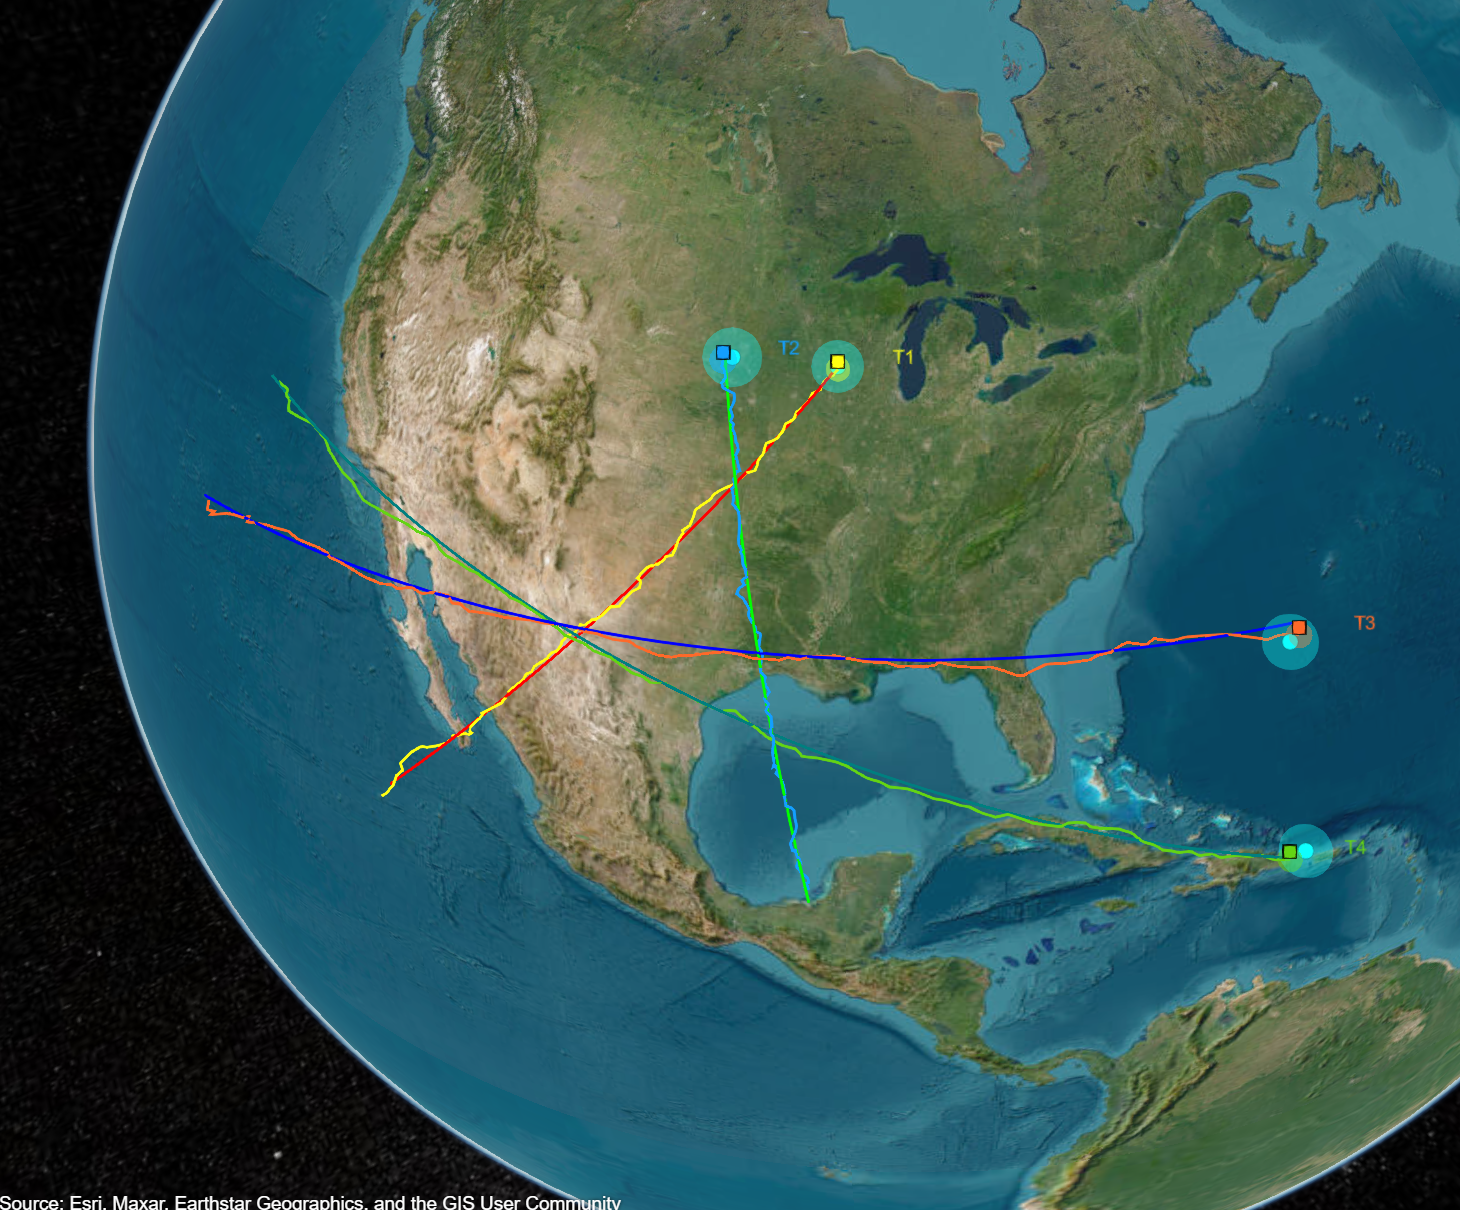

# **Takeaways**

We have established our estimation filter and implemented it as part of our tracking algorithm using a basic tracker: trackerGNN. We then used the same approach to track four satellites passing over the US using trackingGlobeViewer to view our tracking progress in a 3D Earth-Centered view.

**BONUS!**

**BONUS #1 - Explore Tracker Configuration Parameters**

In Exercise 3b, we have configured the GNN and JPDA trackers for you.  The helper function "helperChooseTracker" contains the configuration parameters needed for tracking these data.  Consider opening that function to view the parameters by typing "open helperChooseTracker" in the Command Window.  Alternatively, you can look in the "helperFunctions" folder for the file.